# Fixed-Point Multiplication

In general, a full precision product requires a word length equal to the sum of the word lengths of the operands. 

 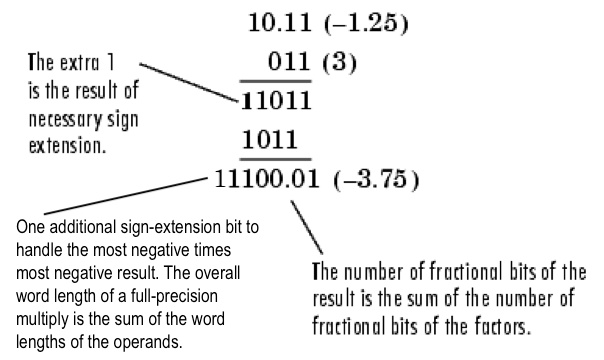

In the following example, note that the word length of the product $c$ is equal to the word length of $a$ plus the word length of $b$. The fraction length of $c$ is also equal to the fraction length of $a$ plus the fraction length of $b$.

a = fi(-1.25,1,4,2)
a.bin

b = fi(3,1,3,0)
b.bin

c = a * b
c.bin

## C code generation

codegen mytimes -args {a,b} -config:lib -launchreport

## HDL code generation

codegen mytimes -args {a,b} -config:hdl -launchreport

## SystemC code generation

cfg = coder.HdlConfig;
cfg.TargetLanguage = "SystemC";
codegen mytimes -args {a,b} -config cfg -launchreport